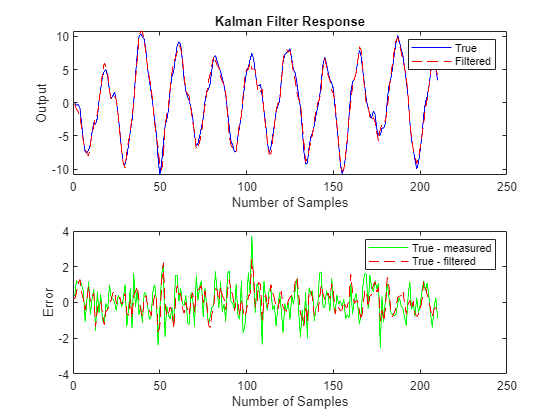

A = [1.1269   -0.4940    0.1129 
     1.0000         0         0 
          0    1.0000         0];

B = [-0.3832
      0.5919
      0.5191];

C = [1 0 0];

D = 0;

Ts = -1;
sys = ss(A,[B B],C,D,Ts,'InputName',{'u' 'w'},'OutputName','y');  % Plant dynamics and additive input noise w

Q = 2.3; 
R = 1; 

[kalmf,L,~,Mx,Z] = kalman(sys,Q,R);

kalmf = kalmf(1,:);

sys.InputName = {'u','w'};
sys.OutputName = {'yt'};
vIn = sumblk('y=yt+v');

kalmf.InputName = {'u','y'};
kalmf.OutputName = 'ye';

SimModel = connect(sys,vIn,kalmf,{'u','w','v'},{'yt','ye'});

t = (1:210)';
u = bre_test_result(:,3);

rng(10,'twister');
w = sqrt(Q)*randn(length(t),1);
v = sqrt(R)*randn(length(t),1);

out = lsim(SimModel,[u,w,v]);

yt = out(:,1);   % true response
ye = out(:,2);  % filtered response
y = yt + v;     % measured response

clf
subplot(211), plot(t,yt,'b',t,ye,'r--'), 
xlabel('Number of Samples'), ylabel('Output')
title('Kalman Filter Response')
legend('True','Filtered')
subplot(212), plot(t,yt-y,'g',t,yt-ye,'r--'),
xlabel('Number of Samples'), ylabel('Error')
legend('True - measured','True - filtered')